## Euclidean VS IED-TW Delay

clc; clear; close all; addpath z_toolbox;
addpath(fullfile('z_toolbox', 'Violinplot'));
load(fullfile('step4_IEDtw_polyfit_TD6d0', 'IEDtw_meth-None_TD-6d0.mat'));
nS = 13; subID = 'sub-0014';
load(fullfile('step2_channelDistance', [subID,'_EuclideabDistanceMatrix.mat']));
IEDtwD = IEDtw(nS).indirectTransferDelayMatrix;
IEDtwR = IEDtw(nS).indirectTransferRateMatrix;
Mask = IEDtwR;
Mask = Mask - diag(diag(Mask));
Mask(isnan(Mask)) = 0;
Mask(Mask<0.1) = 0;
ED = DistanceWorld(Mask>0);
IEDtwD = IEDtwD(Mask>0);
[polyModel, Curve, Ftest] = f_polyfit(ED, IEDtwD, 6);
disp(polyModel.adjR2); disp(Ftest.Fstat); disp(Ftest.p_value);

    0.4079

  653.3888

     0



figure('Units', 'centimeters', 'Position', [5, 5, 36, 20]);
subplot(2, 3, 1);
f_densityScatter(ED, IEDtwD, 2); hold on;
plot(Curve.x, Curve.y, 'r-', 'LineWidth', 2); hold off;
xlim([min(ED), max(ED)]); ylim([min(IEDtwD), max(IEDtwD)]);
xlabel('Euclidean Distance (mm)'); ylabel('IED-TW Delay (ms)');
set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);

## IED-TW Rate VS IED-TW Delay

clc; clear;
load(fullfile('step4_IEDtw_polyfit_TD6d0', 'IEDtw_meth-None_TD-6d0.mat'));
nS = 13; subID = 'sub-0014';
IEDtwD = IEDtw(nS).indirectTransferDelayMatrix;
IEDtwR = IEDtw(nS).indirectTransferRateMatrix;
Mask = IEDtwR;
Mask = Mask - diag(diag(Mask));
Mask(isnan(Mask)) = 0;
Mask(Mask<0.1) = 0;
IEDtwD = IEDtwD(Mask>0);
IEDtwR = IEDtwR(Mask>0);
IEDtwR = log(IEDtwR);
[r,  p] = corr(IEDtwR, IEDtwD, 'Type', 'Spearman');
disp(r), disp(p);

   -0.5229

     0



[polyModel, Curve, Ftest] = f_polyfit(IEDtwR, IEDtwD, 1);
subplot(2, 3, 2);
f_densityScatter(IEDtwR, IEDtwD, 2);
hold on;
plot(Curve.x, Curve.y, 'r-', 'LineWidth', 2); 
hold off;
xlim([min(IEDtwR), max(IEDtwR)]);
ylim([min(IEDtwD), max(IEDtwD)]);
xlabel('log(IED-TW Rate (n/min))');
ylabel('IED-TW Delay (ms)');
set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);

## SC Strength VS IED-TW Delay

clc;clear;
load(fullfile('step2_fiberTrack', 'FiberMatrix_ncount_length_qa_allsubject.mat'), 'fiberCount');
load(fullfile('step4_IEDtw_polyfit_TD6d0', 'IEDtw_meth-None_TD-6d0.mat'));
nS = 13; subID = 'sub-0014';
fibN = fiberCount{nS};
IEDtwD = IEDtw(nS).indirectTransferDelayMatrix;
IEDtwR = IEDtw(nS).indirectTransferRateMatrix;
Mask = IEDtwR;
Mask = Mask - diag(diag(Mask));
Mask(isnan(Mask)) = 0;
Mask(Mask<0.1) = 0; 
Mask(fibN==0) = 0;
IEDtwD = IEDtwD(Mask>0);
fibN = fibN(Mask>0);
fibN = log(fibN);
[r, p] = corr(fibN, IEDtwD, 'Type', 'Spearman');
disp(r); disp(p);

   -0.4429

   1.4223e-40



[polyModel, Curve, Ftest] = f_polyfit(fibN, IEDtwD, 1);
subplot(2, 3, 3);
f_densityScatter(fibN, IEDtwD, 2);
hold on;
plot(Curve.x, Curve.y, 'r-', 'LineWidth', 2);
hold off;
xlim([min(fibN), max(fibN)]);
ylim([min(IEDtwD), max(IEDtwD)]);
xlabel('SC Strength'); 
ylabel('IED-TW Delay (ms)');
set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);

## Adjusted R2 of polynomial fitting between Euclidean Distance and IED-TW delays

clc; clear; 
load(fullfile('step4_IEDtw_polyfit_TD6d0', ...
    'IEDtw_meth-none_TD-6d0_polyfit-edisVSdelay_rateVSdelay.mat'), 'adjR2_twDED');
[~, order_opt] = max(mean(adjR2_twDED, 1)); disp(order_opt);

     6



adjR2_twDED_true = mean(adjR2_twDED(:, order_opt), 2);
disp(mean(adjR2_twDED_true)); disp(std(adjR2_twDED_true));

    0.2302

    0.1177



trueStr = cell(length(adjR2_twDED_true), 1);
for n = 1:length(trueStr)
    trueStr{n} = 'Empirical';
end
load(fullfile('step4_IEDtw_polyfit_TD6d0', ...
    'IEDtwNull_meth-none_TD-6d0_polyfit_distanceVSdelay_rateVSdelay.mat'), 'adjR2_twDED');
adjR2_twDED_as_null = mean(mean(adjR2_twDED(:, 4:6, :), 3), 2);
nullStr = cell(length(adjR2_twDED_as_null), 1);
for n = 1:length(nullStr)
    nullStr{n} = 'Null';
end
adjR2 = [adjR2_twDED_true; adjR2_twDED_as_null];
Origin = [trueStr; nullStr];
subplot(2, 3, 4);
vs = violinplot(adjR2, Origin, 'QuartileStyle','shadow', ...
    'Width', 0.2, 'GroupOrder', {'Empirical', 'Null'}, ...
    'ViolinColor', [0.95, 0.27, 0.1; 0.4, 0.4, 0.4], ...
    'ShowMean', true, 'ViolinAlpha', 0.5, ...
    'MarkerSize', 35);
xlim([0.3, 2.7]); ylabel('Adjusted R^2');
set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);
x = adjR2_twDED_true(:); y = adjR2_twDED_as_null(:);
[p, h, stats] = ranksum(x, y, 'tail', 'both', 'method', 'approximate');
z = stats.zval; cliffDelta = f_cliff_delta(x, y);
df = length(x)+length(y)-2;
disp(['p = ', num2str(p), ' z = ', num2str(z), ...
    ' Cliff Delta = ', num2str(cliffDelta), ' df = ', num2str(df)]);

p = 1.382e-14 z = 7.698 Cliff Delta = 0.92214 df = 92


## Spearman R between IED TW Rate And IED TW Delay

clc; clear; 
load(fullfile('step4_IEDtw_polyfit_TD6d0', ...
    'IEDtw_meth-none_TD-6d0_polyfit-edisVSdelay_rateVSdelay.mat'), 'R_twDR')
R_twDR_true = R_twDR'; trueStr = cell(length(R_twDR_true), 1);
for n = 1:length(trueStr)
    trueStr{n} = 'Empirical';
end
load(fullfile('step4_IEDtw_polyfit_TD6d0', ...
    'IEDtwNull_meth-none_TD-6d0_polyfit_distanceVSdelay_rateVSdelay.mat'), 'R_twDR')
R_twDR_null = mean(R_twDR, 2); nullStr = cell(length(R_twDR_null), 1);
for n = 1:length(nullStr)
    nullStr{n} = 'Null';
end
R = [R_twDR_true; R_twDR_null]; Origin = [trueStr; nullStr];
disp(mean(R_twDR_true)); disp(std(R_twDR_true));

   -0.3313

    0.1678



subplot(2, 3, 5);
vs = violinplot(R, Origin, 'QuartileStyle','shadow', ...
    'Width', 0.2, 'GroupOrder', {'Empirical', 'Null'}, ...
    'ViolinColor', [0.95, 0.27, 0.1; 0.4, 0.4, 0.4], ...
    'ShowMean', true, 'ViolinAlpha', 0.5, ...
    'MarkerSize', 35);
xlim([0.3, 2.7]); ylabel('Spearman Correlation');
set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);
x = R_twDR_true(:); y = R_twDR_null(:);
[p, h, stats] = ranksum(x, y, 'tail', 'both', 'method', 'approximate');
z = stats.zval; cliffDelta = f_cliff_delta(x, y);
df = length(x) + length(y) - 2;
disp(['p = ', num2str(p), ' z = ', num2str(z), ...
    ' Cliff Delta = ', num2str(cliffDelta), ' df = ', num2str(df)]);

p = 2.9755e-08 z = -5.5429 Cliff Delta = -0.6641 df = 92


## Spearman R between SC Strength and IED-TW Delay

clc;clear;
load(fullfile('step4_IEDtw_polyfit_TD6d0', ...
    'IEDtw_meth-none_TD-6d0_polyfit-fibnVSdelay.mat'), 'R_fibNtwD');
R_fibNtwD_true = R_fibNtwD';
[a, b] = min(R_fibNtwD_true);
R_fibNtwD_true(R_fibNtwD_true==0) = [];
trueStr = cell(length(R_fibNtwD_true), 1);
for n = 1:length(trueStr)
    trueStr{n} = 'Empirical';
end
load(fullfile('step4_IEDtw_polyfit_TD6d0', ...
    'IEDtwNull_meth-none_TD-6d0_polyfit-fibnVSdelay.mat'), 'R_fibNtwD');
R_fibNtwD_null = mean(R_fibNtwD, 2);
R_fibNtwD_null(R_fibNtwD_null==0) = [];
nullStr = cell(length(R_fibNtwD_null), 1);
for n = 1:length(nullStr)
    nullStr{n} = 'Null';
end
R = [R_fibNtwD_true; R_fibNtwD_null];
Origin = [trueStr; nullStr];
disp(mean(R_fibNtwD_true)); disp(std(R_fibNtwD_true));

   -0.3501

    0.1026



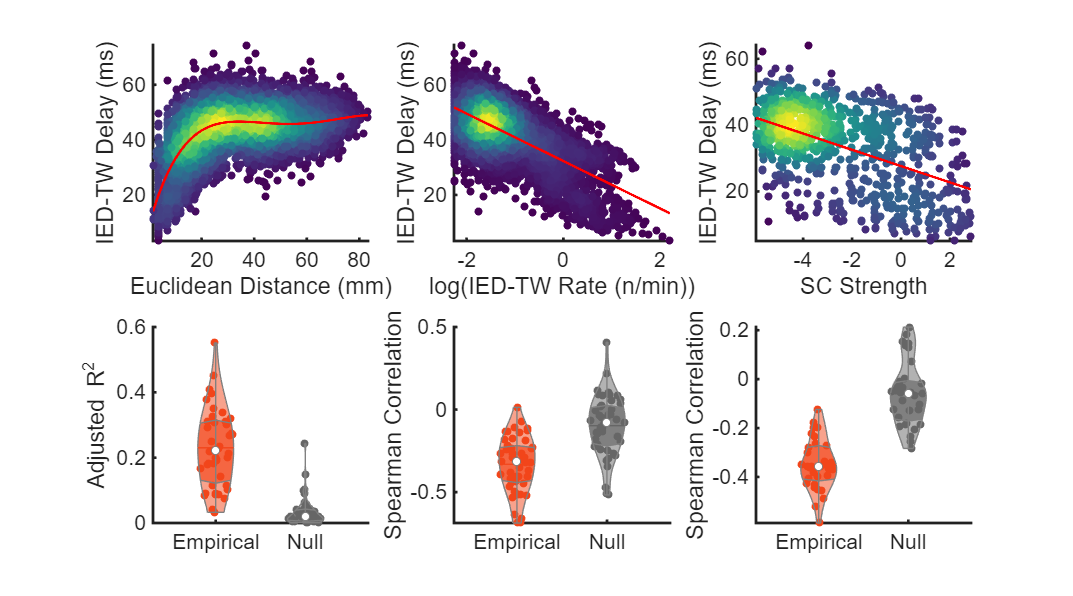

subplot(2, 3, 6);
vs = violinplot(R, Origin, 'QuartileStyle','shadow', ...
    'Width', 0.2, 'GroupOrder', {'Empirical', 'Null'}, ...
    'ViolinColor', [0.95, 0.27, 0.1; 0.4, 0.4, 0.4], ...
    'ShowMean', true, 'ViolinAlpha', 0.5, ...
    'MarkerSize', 35);
xlim([0.3, 2.7]); ylabel('Spearman Correlation');
set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);

x = R_fibNtwD_true(:); y = R_fibNtwD_null(:);
[p, h, stats] = ranksum(x, y, 'tail', 'both', 'method', 'approximate');
z = stats.zval; cliffDelta = f_cliff_delta(x, y);
df = length(x) + length(y) - 2;
disp(['p = ', num2str(p), ' z = ', num2str(z), ...
    ' Cliff Delta = ', num2str(cliffDelta), ' df = ', num2str(df)]);

p = 6.6808e-11 z = -6.5277 Cliff Delta = -0.93572 df = 64
